# Integrate Motor-CAD SaturationLossMap.mat and Calibrate PMSM Control Lookup Tables 

*Copyright 2026 The MathWorks, Inc.*

Use this script to preprocess PMSM data for use in model-based calibration (MBC) and autogenerate current controller calibration tables using the `mbcrunner API`. This script produces the table object, `MBCdata`, for use in MBC. You can import the `MBCdata` object into MBC from the workspace or use the object together with model fitting and CAGE template in the mbcrunner() API function to generate torque tables for a PMSM. 

PMSM characterization data can come from a finite element analysis simulation or dynamometer testing. This example uses the SaturationLossMap.mat from Motor-CAD and uses scatteredInterpolant for interpolating non-cartesian data.

## 1. Load Raw SaturationLossMap

clear
warning('off','all')   % suppress warning
load('SaturationLossMap.mat')
Fluxd = Flux_Linkage_D;
Fluxq = Flux_Linkage_Q;
Id = Id_Peak;
Iq = Iq_Peak;
Trq = Electromagnetic_Torque;
Rs = Phase_Resistance_DC_at_20C;
pp = PolePairs;

Process raw data from SaturationLossMap.mat for FEM-Parameterized PMSM block

Shaft_Speed = 2000;
MagVec = Stator_Current_Phase_Peak(:,1)';
gammaVec = Phase_Advance(1,:);% current advance angle must be ascending in Simscape
angleVec = -DriveOffsetAngleLoad/pp + squeeze(Angular_Rotor_Position(1,1,:))'/pp;
Fd = Angular_Flux_Linkage_D;
Fq = Angular_Flux_Linkage_Q;
torqueMat= Angular_Electromagnetic_Torque;

## 2. Visualize Flux Linkage and Torque Data

Visualize the flux linkages data with respect to the d-axis and q-axis currents.

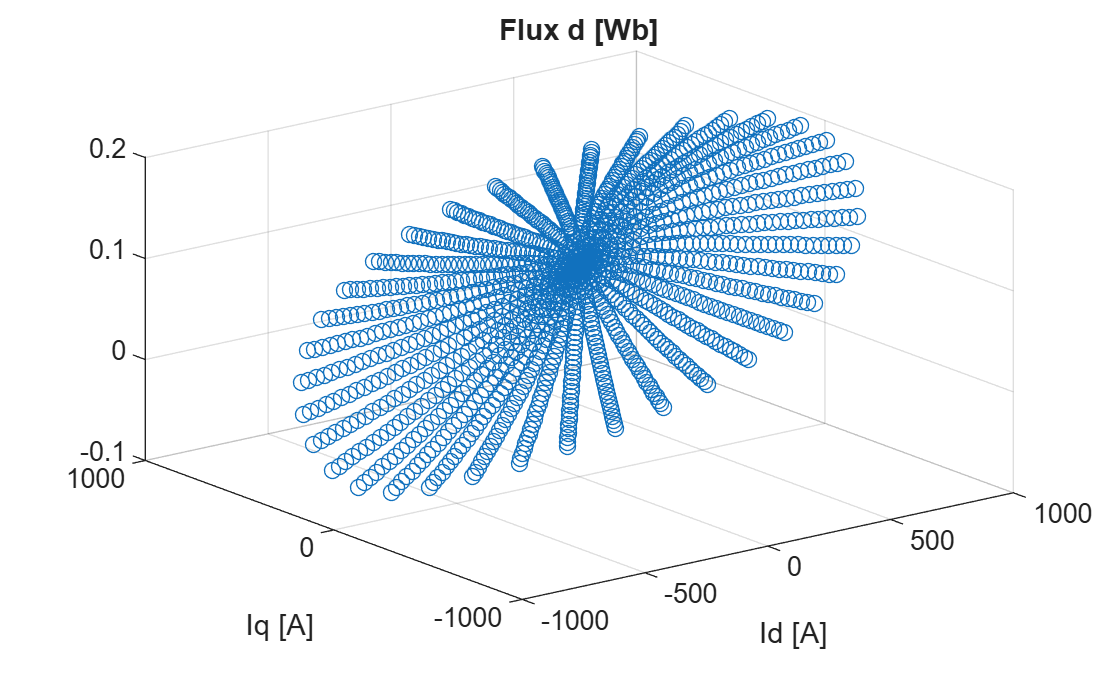

stem3(Id,Iq,Fluxd,"LineStyle","none");
title("Flux d [Wb]");
xlabel("Id [A]");ylabel("Iq [A]");

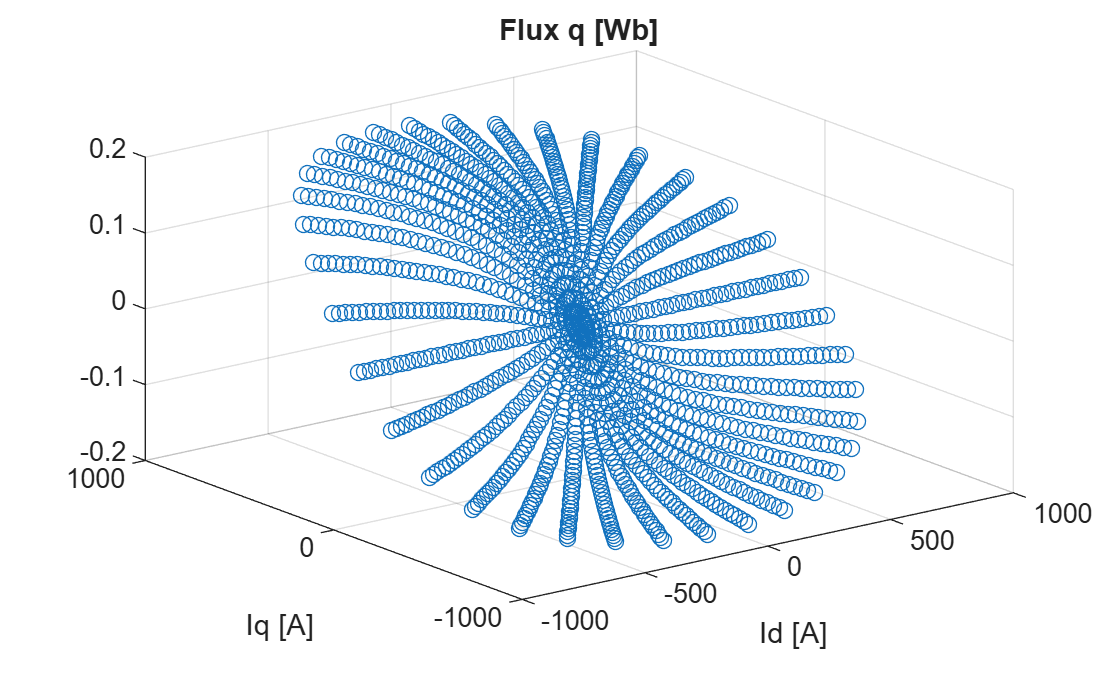

stem3(Id,Iq,Fluxq,"LineStyle","none");
title("Flux q [Wb]");
xlabel("Id [A]");
ylabel("Iq [A]");

Visualize the torque data with respect to the d-axis and q-axis currents.

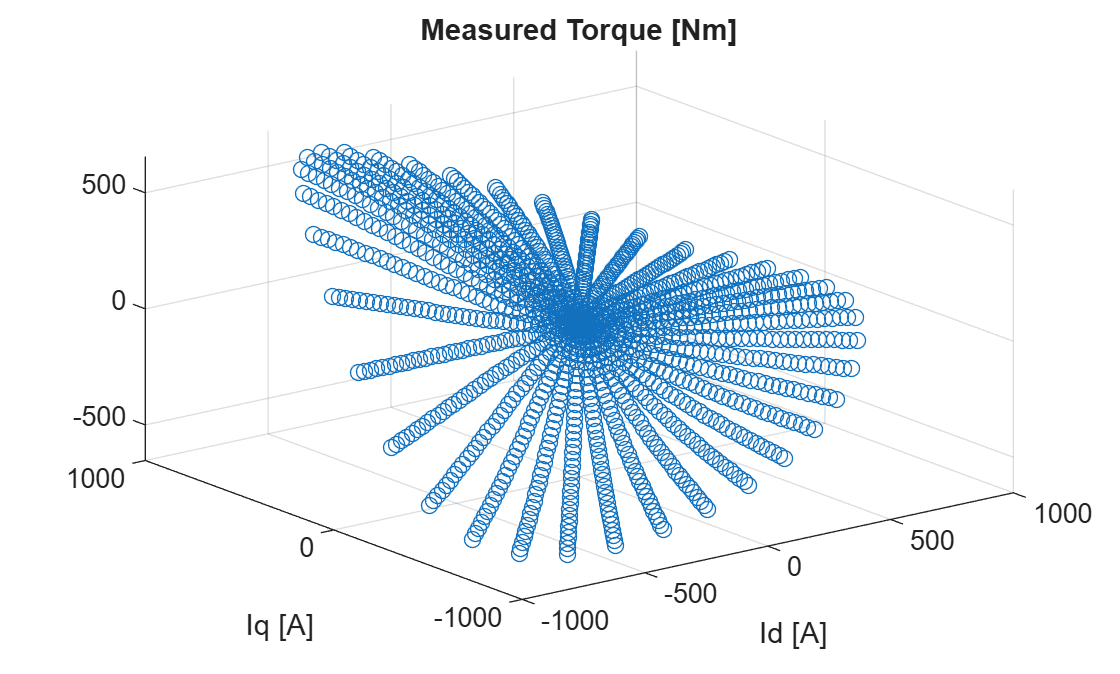

stem3(Id,Iq,Trq,"LineStyle","none");
title("Measured Torque [Nm]");
xlabel("Id [A]");
ylabel("Iq [A]");

## 3.Define PMSM Control Specification

Specify the DC voltage `Vdc`, number of pole pairs `pp`,  phase peak current `IsMax`, and maximum modulation voltage `VsMax` to align with your PMSM specification. 

Vdc = 720;
IsMax = 900;
MI = 0.97;
VsMax = MI*Vdc/sqrt(3);

Note that `VsMax=Vdc*(2/pi)` is the maximum fundamental voltage of an inverter drive, calculated by applying a 6-step inverter-controlled voltage to an AC motor and performing a fast fourier transform on the output 6-step waveform. If you apply SVPWM and stay in linear modulation, then `VsMax` = `Vdc`/`sqrt(3)`.

## **4.Process Motor-CAD Data for FEM-Parameterized PMSM Block and Controls**

Calculate gridded data, [`IDgrid`,`IQgrid`], using [`ndgrid`](docid:matlab_ref#bvkap7w) to create a grid for cartesian interpolation

idAxis = linspace(-IsMax,0,51); 
iqAxis = linspace(0,IsMax,53);
[IDgrid,IQgrid] = ndgrid(idAxis,iqAxis);


Calculate interpolants for flux linkage data

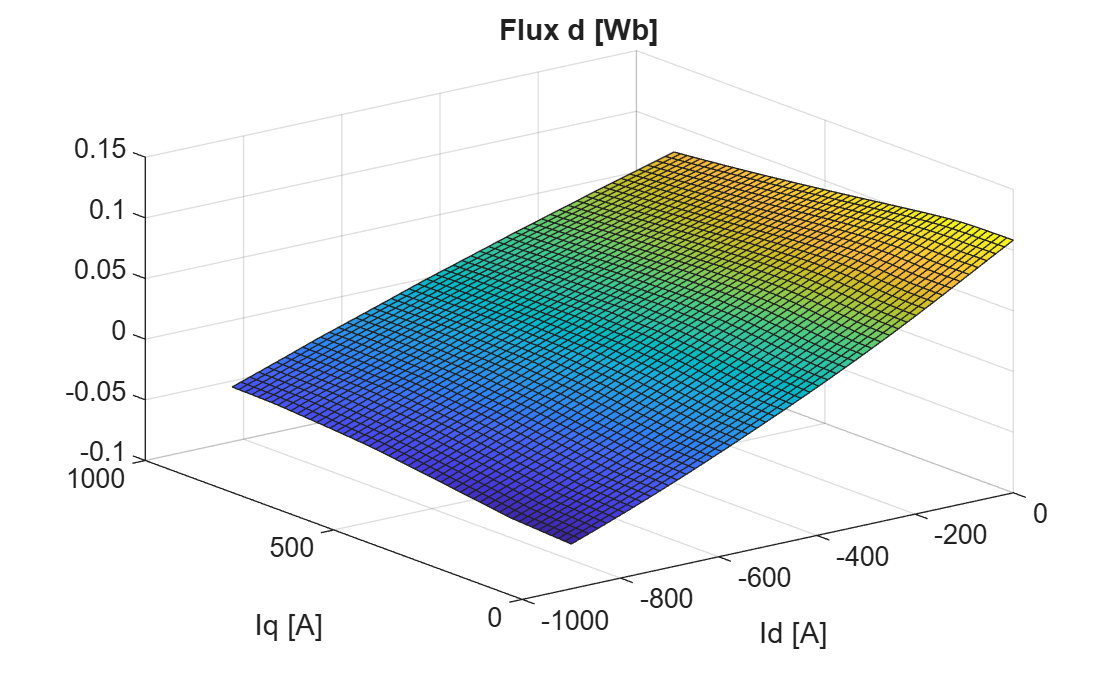

F_lambdad = scatteredInterpolant(Id_Peak(:), Iq_Peak(:), Fluxd(:), 'natural');
F_lambdaq = scatteredInterpolant(Id_Peak(:), Iq_Peak(:), Fluxq(:), 'natural');

lambdad = F_lambdad(IDgrid, IQgrid);
surf(IDgrid,IQgrid,lambdad);
title("Flux d [Wb]");
xlabel("Id [A]");
ylabel("Iq [A]");

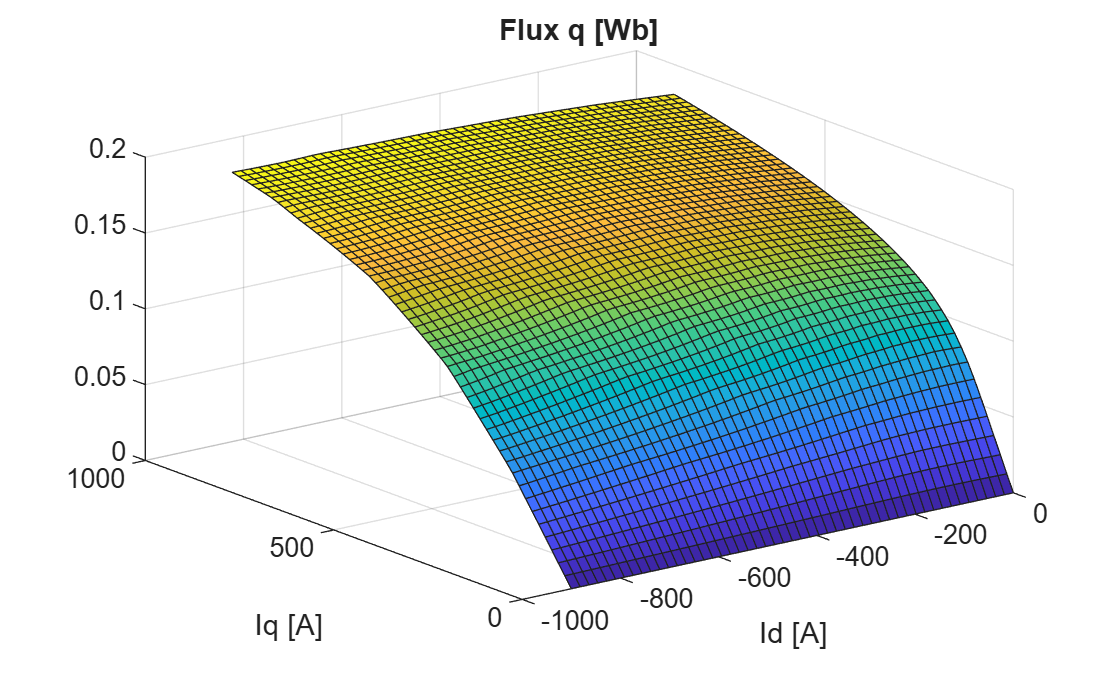


lambdaq = F_lambdaq(IDgrid, IQgrid);
surf(IDgrid,IQgrid,lambdaq);
xlabel("Id [A]");
ylabel("Iq [A]");
title("Flux q [Wb]");

Calculate interpolants for torque data. The calculated torque is derived from flux linkage and current data.

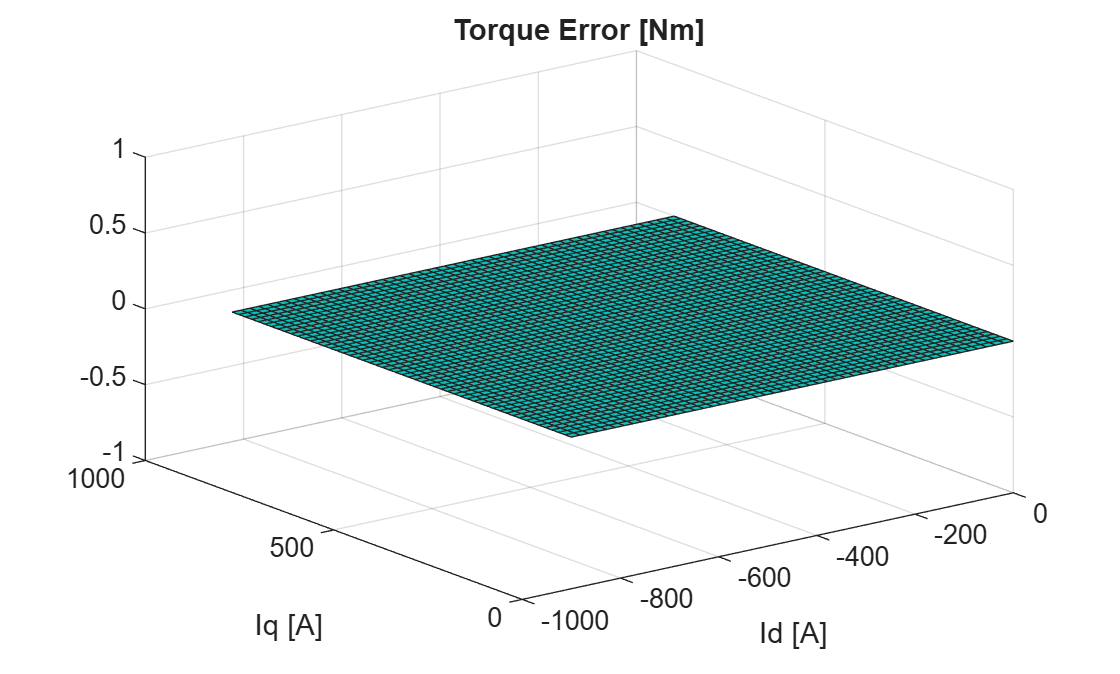

calculatedTorque(:) = ...
    -1.5*pp*(Id_Peak(:).*Fluxq(:) - Iq_Peak(:).*Fluxd(:));

F_calculatedTorque = scatteredInterpolant(Id_Peak(:), Iq_Peak(:), calculatedTorque(:), 'natural');
F_Tem = scatteredInterpolant(Id_Peak(:), Iq_Peak(:), Electromagnetic_Torque(:), 'natural');

T_calc = F_calculatedTorque(IDgrid, IQgrid);
T_em = F_Tem(IDgrid, IQgrid);

surf(IDgrid,IQgrid,T_em- T_calc);
title("Torque Error [Nm]");
xlabel("Id [A]");
ylabel("Iq [A]");

Calculate interpolants for loss data.

F_DCLoss = scatteredInterpolant(Id_Peak(:), Iq_Peak(:), Stator_Copper_Loss_DC(:), 'natural', 'none');
F_ACLoss = scatteredInterpolant(Id_Peak(:), Iq_Peak(:), Stator_Copper_Loss_AC(:), 'natural', 'none');
F_HystCoeff = scatteredInterpolant(Id_Peak(:), Iq_Peak(:), Iron_Loss_Hysteresis_Coefficient(:), 'natural', 'none');
F_EddyCoeff = scatteredInterpolant(Id_Peak(:), Iq_Peak(:), Iron_Loss_Eddy_Coefficient(:), 'natural', 'none');
F_MagLoss   = scatteredInterpolant(Id_Peak(:), Iq_Peak(:), Magnet_Loss(:),'natural', 'none');
f_base = Frequency;  % FEA operating frequency [Hz] (200 Hz)

Calculate incremental inductance for closed-loop control gain scheduling

did = idAxis(2) - idAxis(1);
diq = iqAxis(2) - iqAxis(1);
[Ldq, Ldd] = gradient(lambdad, diq, did);
[Lqq, Lqd] = gradient(lambdaq, diq, did);

Additional control parameters

BW = 750; % Hz, current loop bandwidth
F_sw = 10000; % switching frequency
Tst = 1/F_sw; % switching period
Ts = 2/(100*F_sw); % sample time
Ki_d = 2*pi*BW*Rs;
Ki_q = 2*pi*BW*Rs;
Rload = 1e6;

## 5. Define Operating Points

Specify the number of torque operating points `numTorqueLevels` and the low torque levels `minTorqueLevels`. The remaining torque levels are evenly spaced up to the maximum measured torque. Torque is specified in Nm.

numTorqueLevels = 50;
minTorqueLevels = [1 5 10 20];

Downsample by a factor of 5.

downsampleFactor = 5;

Specify minimum speed `speedMin`, maximum speed `speedMax`, and speed step size `speedStep` to define speed operating points. Speed does not need to be evenly spaced, but some steps in MBC are easier with evenly spaced speed operating points. Speed is specified in rpm.

Speed is a lookup table input. Match operating points to breakpoints.

speedMin = 1000;
speedMax = 15000;
speedStep = 250;

speed = speedMin:speedStep:speedMax;
speedBreakpoints = speed;

## Rearrange Data in Torque-Speed Operating Points

Introduce torque as an operating point in addition to speed by rearranging the data to have both torque and speed information.

### Calculate Torque Contour Levels

Initialize the torque contours at the levels in `minTorqueLevels`. Then, evenly space the levels up to the maximum measured torque.

TrqMax = max(abs(T_em),[],"all");
numPoints = numTorqueLevels-length(minTorqueLevels)+1;
torqueLevels = ...
[minTorqueLevels(1:end-1) linspace(minTorqueLevels(end),TrqMax,numPoints)];

### Create and Plot Torque Contour

Create and plot torque contour using the [`contour`](docid:matlab_ref#f19-795863) function.

`trqContour` is a 2x*N* array containing sets of contour data for each contour level.


$$\left\lbrack \begin{array}{cc}
Z_i  & X_i \\
N_i  & Y_i 
\end{array}\right\rbrack$$
 

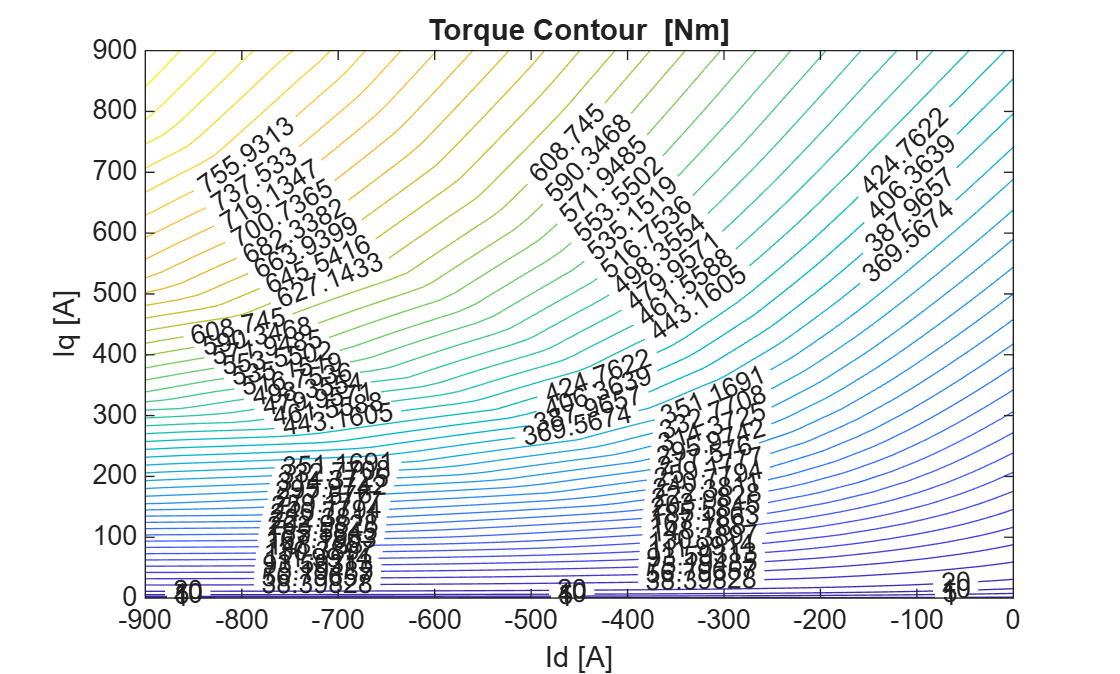

trqContour = contour(IDgrid,IQgrid,T_em,torqueLevels, ...
    "ShowText","on");
title("Torque Contour  [Nm]");
xlabel("Id [A]");
ylabel("Iq [A]");

### Rearrange Data by Torque Levels

For each torque level, extract the `Trq`, `Id`, and `Iq` values. Next, downsample data for the torque level. If you have a Signal Processing Toolbox™ license, use the `downsample` function to calculate `dataDownsample`. Then, expand each torque level to include all speeds, attaching every speed operating point to each (`id`, `iq`) on the torque contour.

start = 1;
accumulatedData = []; 
while start < size(trqContour,2)
    % process each torque levels (the contour levels). 
    % There may be some contour lines missing

    currentTorque = trqContour(1,start);

    % The number of points in the contour for this torque.
    ni = trqContour(2,start);
    stop = start + ni;
    
    % Extract [Trq, Id, Iq] for current torque level.
    torqueData = [repelem(currentTorque,ni) ; 
    trqContour(:,start+1:stop)]'; % [Id, Iq] points for current torque
    
    if false
        dataDownsample = downsample(torqueData,downsampleFactor);
    else
        dataDownsample = torqueData(1:downsampleFactor:end,:);
    end
    
    if ( dataDownsample(end,2)~= torqueData(end,2) ) 
        % Make sure we have the last point in contour
        torqueData = [dataDownsample;torqueData(end,:)];
    else
        torqueData = dataDownsample;
    end
    ni = size(torqueData,1);
    
    % Repeat torque contours for each speed and accumulate data.
    % Make sure speed is a column vector [Trq, Id, Iq, n].
    accumulatedData=[accumulatedData; ...
    repmat(torqueData,[length(speed),1]) repelem(speed(:),ni)];

    % Start of next torque contour.
    start = stop+1;
end



## 6. Create Table Object with Preprocessed Data

Store `accumulatedData` with the variables `Trq`, `Id`, `Iq`, and `n` to the table, `MBCdata`.

MBCdata = array2table(accumulatedData,VariableNames=["T_em","Id","Iq","n"]);

Calculate Shaft Torque T_shaft based on frequency-scaled loss data.

%Shaft torque = T_em − (iron + magnet losses) / ω_mech
f = MBCdata.n*PolePairs/60;
omega_mech = MBCdata.n*2*pi/60;
MBCdata.T_shaft = MBCdata.T_em - (F_HystCoeff(MBCdata.Id,MBCdata.Iq).*f + F_EddyCoeff(MBCdata.Id,MBCdata.Iq).*f.^2+...
                  F_MagLoss(MBCdata.Id,MBCdata.Iq).*(f/f_base).^2)./omega_mech;


Calculate the derived quantities:  peak current `MBCdata.Is`, voltage `MBCdata.Vs`, resultant flux `MBCdata.Flux`, and maximum flux `MBCdata.FluxMax`. 

Note that `MBCData.FluxMax` is derived from steady state voltage and torque equations.


MBCdata.Is = sqrt(MBCdata.Id.^2 + MBCdata.Iq.^2);

% electrical speed [rad/s]
we = 2*pi.*MBCdata.n.*pp./60;

Flux_d = interpn(idAxis,iqAxis,lambdad,MBCdata.Id,MBCdata.Iq);
Flux_q = interpn(idAxis,iqAxis,lambdaq,MBCdata.Id,MBCdata.Iq);

Vd = Rs.*MBCdata.Id - we.*Flux_q;
Vq = Rs.*MBCdata.Iq + we.*Flux_d;
MBCdata.Vs = sqrt(Vd.^2 + Vq.^2);


Calculate total loss:

%   P_total = P_DC_copper                                (speed-independent)
%           + P_AC_copper * (f / f_base)^2               (skin/proximity effect)
%           + Iron_Hyst_Coefficient * f                  (hysteresis: linear in f)
%           + Iron_Eddy_Coefficient * f^2                (eddy current: quadratic in f)
%           + Magnet_Loss * (f / f_base)^2               (magnet eddy: quadratic in f)

MBCdata.Loss = F_DCLoss(MBCdata.Id,MBCdata.Iq)                  +...
               F_ACLoss(MBCdata.Id,MBCdata.Iq).*(f/f_base).^2   +...
               F_HystCoeff(MBCdata.Id,MBCdata.Iq).*f            +...
               F_EddyCoeff(MBCdata.Id,MBCdata.Iq).*f.^2         +...
               F_MagLoss(MBCdata.Id,MBCdata.Iq).*(f/f_base).^2;


Set the units for each of the variables in the `MBCdata` table object.

                                  % T_em  Id  Iq   n  T_shaft  Is  Vs  Loss
MBCdata.Properties.VariableUnits = ["Nm","A","A","rpm","Nm", "A","V","W"];


## 7. Generate Calibration Using MBC API

Programmatically fit models with the preprocessed data, `MBCData`, and generate optimal current controller calibration tables using MBC functions.

IsMax = 650.5;  % update IsMax for calibration
proj = mbcmodel.CreateProject('PMSM_Calibrate');

Create the data object, D, in the project object, proj, from the MBCdata table object. Open it for editing.

D = CreateData(proj,MBCdata);BeginEdit(D);

Sort the data points by speed, grouping those within a 0.5 tolerance of each other.

DefineTestGroups(D,{'n'},0.5,'',true);

Filter the data retaining current values that are within a 20% margin above the maximum value of the phase peak current, IsMax, and voltage values that are within a 50% margin above the maximum modulation voltage, VsMax.

AddFilter(D,sprintf('Is<=1.2*%g',IsMax));
AddFilter(D,sprintf('Vs<=1.5*%g',VsMax));
CommitEdit(D);

Create the test plan, `T`, and attach the data, `D`, to fit the models in the PMSM template, PMSM_Speed, provided with this example.

MBCModelTemplate = 'ModelFittingwithLoss_R26a';
T = CreateTestplan(proj,MBCModelTemplate);
T.Name = 'Models';
AttachData(T,D,'UseDataRange',true,'Boundary',true);

Generate optimal calibrations with the optimizations defined in the PMSM CAGE template project, `PMSM_Speed.cag`, provided with this example.

CAGETemplate = 'CAGEprjwithLoss_R26a.cag';

Create an mbcrunner object to the CAGE template project, `CAGETemplate`, to programmatically run CAGE operations.

runner = mbcrunner(CAGETemplate);

Define the lookup table breakpoints using the speed and torque percent breakpoints.

torquePercentBreakpoints = [1 4:4:100];
breakPoints = {speedBreakpoints, torquePercentBreakpoints};

Update the `Id_Table` and `Iq_Table` and `TrqEnvelope` breakpoints in the CAGE project with the look up table breakpoints, `breakPoints`

updateBreakpoints(runner,'Id_Table',breakPoints,true);

Update constraint bounds for the phase current, `Is`, and phase voltage, `Vs`, for the torque model and minimum loss optimizations in the CAGE project.

updateConstraints(runner,'TrqModel_Optimization','Is', ...
    IsMax,'Vs',VsMax)
updateConstraints(runner,'Loss_Optimization','Is_TrqGrid', ...
    IsMax,'Vs_TrqGrid',VsMax)

Update the models and rerun optimizations to fill the lookup tables.

importModels(runner,proj);


## 8. View Lookup Tables

### Torque Envelope

Plot the maximum torque envelope using `optimalTables.SpeedBreakpoints` and `optimalTables.TrqEnvelope`.

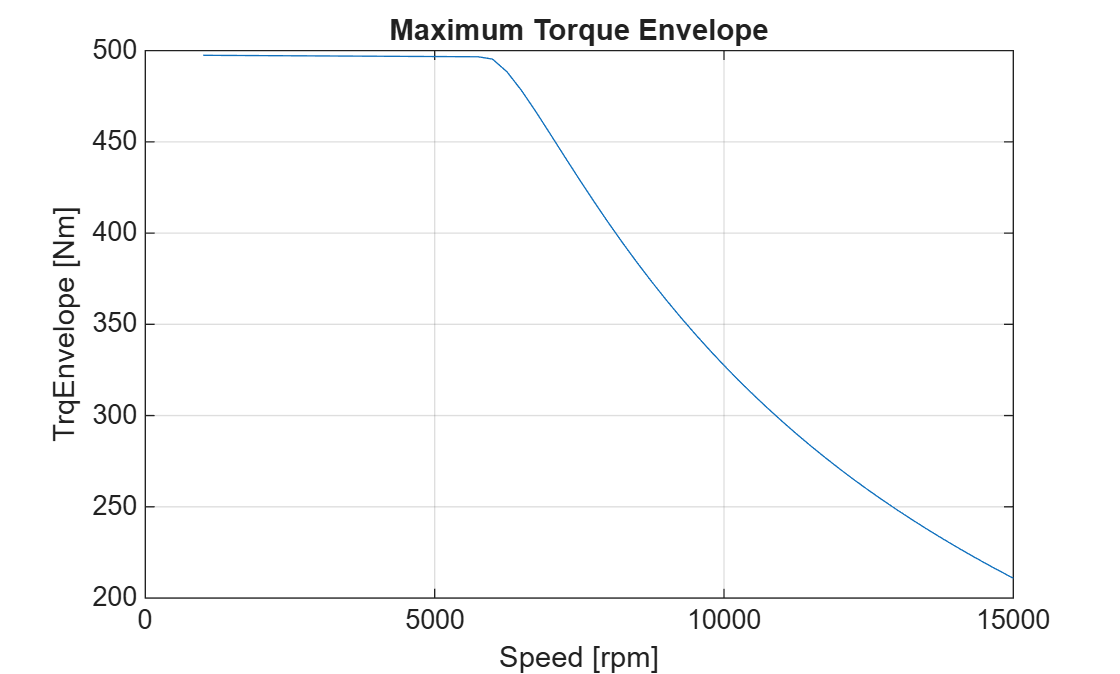

optimalTables = runner.TableValues;
figure
plot(optimalTables.n_norm,optimalTables.TrqEnvelope);
xlabel("Speed [rpm]");
ylabel("TrqEnvelope [Nm]");
title("Maximum Torque Envelope");
grid on

### `Id` Table

Plot the `Id` Table using `optimalTables.TrqPercent_norm`, `optimalTables.n_norm`, and `optimalTables.Id_Table`.

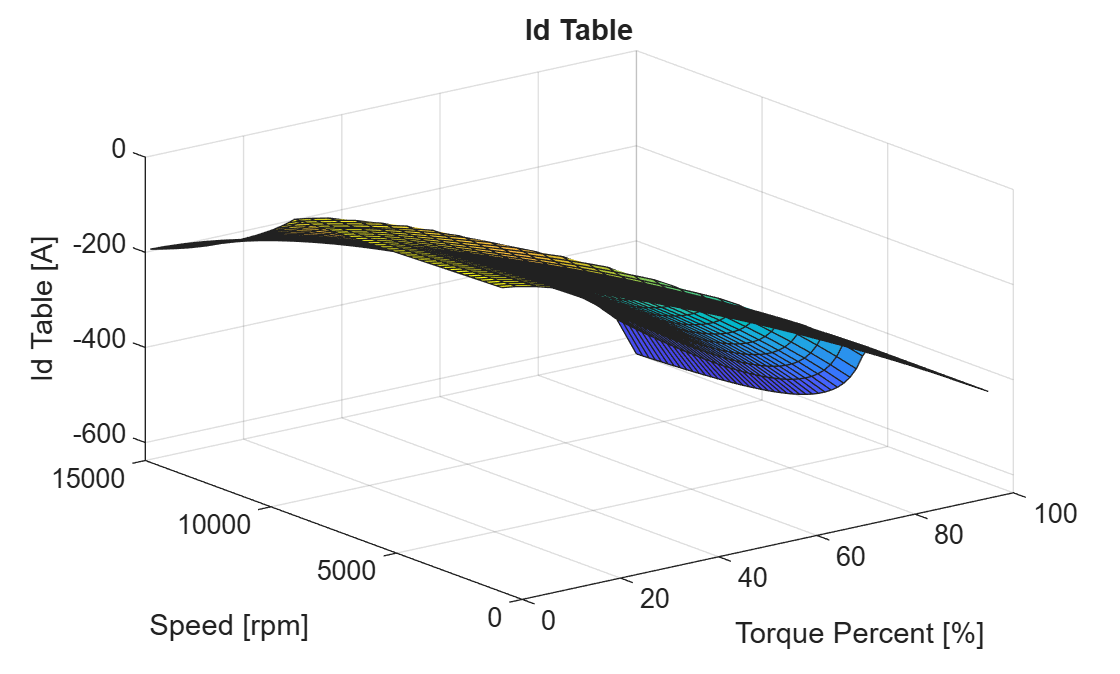

surf(optimalTables.TrqPercent_norm, ...
    optimalTables.n_norm,optimalTables.Id_Table);
xlabel("Torque Percent [%]");
ylabel("Speed [rpm]");
zlabel("Id Table [A]");
title("Id Table");

### `Iq` Table

Plot the `Iq` Table using `optimalTables.TrqPercent_norm`, `optimalTables.n_norm`, and `optimalTables.Iq_Table`.

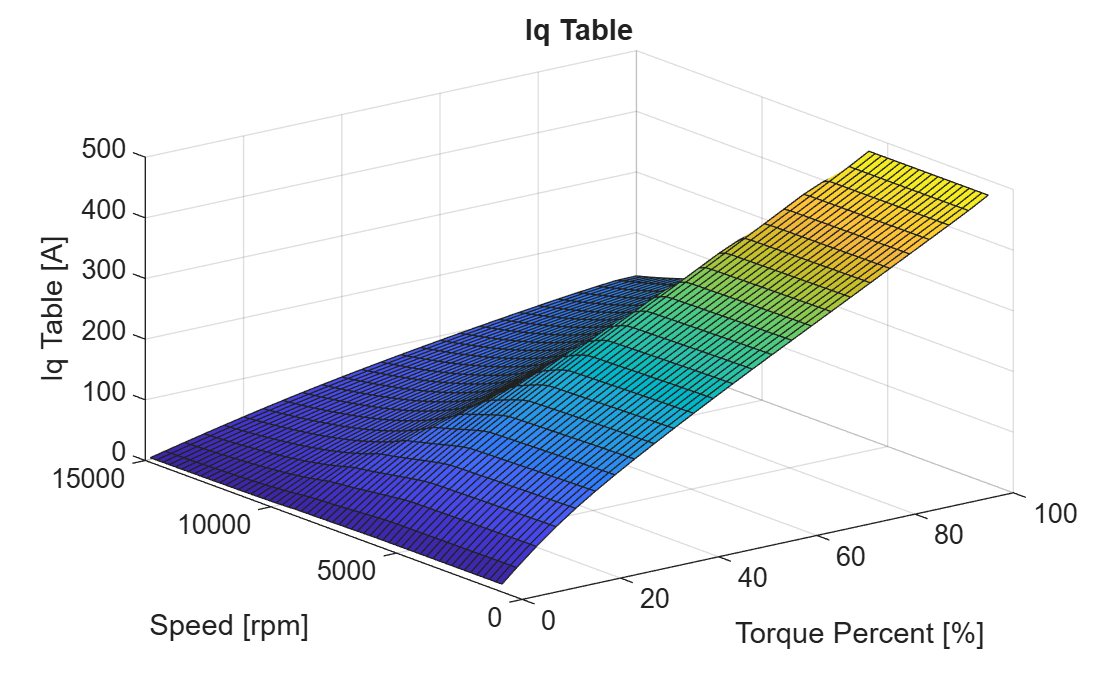

surf(optimalTables.TrqPercent_norm, ...
    optimalTables.n_norm,optimalTables.Iq_Table);
xlabel("Torque Percent [%]");
ylabel("Speed [rpm]");
zlabel("Iq Table [A]");
title("Iq Table");

### `Optimal Operating Points Plotted on Id-Iq Plane`

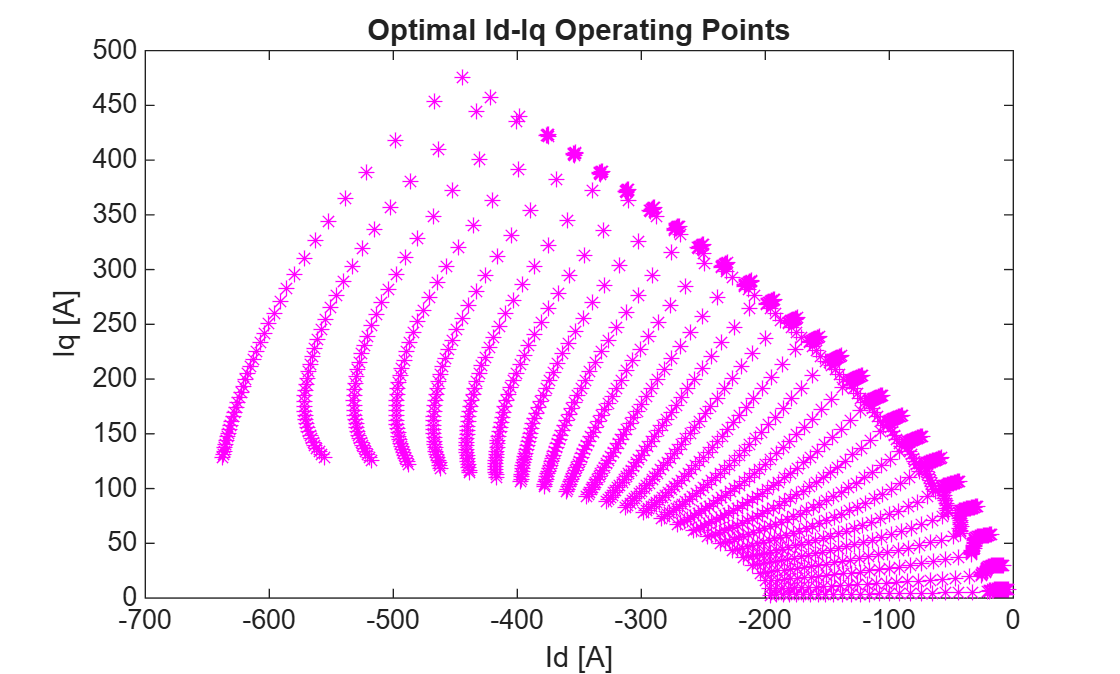

plot(optimalTables.Id_Table,optimalTables.Iq_Table,'m*');xlabel("Id [A]");ylabel("Iq [A]");title("Optimal Id-Iq Operating Points");

## 9. Loss breakdown at 100% torque across speeds

nSpeeds= size(speed,2);
ti100 = find(optimalTables.TrqPercent_norm == 100);
DC_loss_100  = zeros(nSpeeds,1); AC_loss_100  = zeros(nSpeeds,1);
Fe_loss_100  = zeros(nSpeeds,1); Mg_loss_100  = zeros(nSpeeds,1);
for si = 1:nSpeeds
    Id = optimalTables.Id_Table(si, ti100); Iq = optimalTables.Iq_Table(si, ti100);
    if isnan(Id), continue; end
    f  = optimalTables.n_norm(si) * pp / 60;
    DC_loss_100(si) = F_DCLoss(Id,Iq);
    AC_loss_100(si) = F_ACLoss(Id,Iq) * (f/f_base)^2;
    Fe_loss_100(si) = F_HystCoeff(Id,Iq)*f + F_EddyCoeff(Id,Iq)*f^2;
    Mg_loss_100(si) = F_MagLoss(Id,Iq)*(f/f_base)^2;
end
% figure('Name','Validation: Loss Breakdown', 'Position',[250 250 800 400])
area(speed, [DC_loss_100, AC_loss_100, Fe_loss_100, Mg_loss_100]/1000);
legend({'DC Copper','AC Copper','Iron (Fe)','Magnet'}, 'Location','northwest');
xlabel('Speed [RPM]'); ylabel('Loss [kW]');
title('Loss Breakdown at 100% Torque vs Speed'); grid on;

*Copyright 2026 The MathWorks, Inc.*